# آنالیز حساسیت

در این فایل به دنبال این هستیم که تاثیر تغییرات هر پارامتر بر پاسخ سیستم بررسی کنیم. به دلیل تدریس نشدن پاسخ فرکانسی در هنگام نوشتن فایل، تنها تاثیر آن بر پاسخ زمانی بررسی خواهد شد

## تعریف پارامتر قابل تنظیم

برای تحلیل حساسیت ابتدا یک متغیر قابل تنظیم را در مدل قرار می دهیم. این پارامتر بایستی با تابع زیر تعریف شود

`p = realp(paramname,initvalue)`

paramname: اسم پارامتر قابل تغییر در نمایش سیستم همین خواهد بود که با یک رشته مشخص میشود. پیشنهاد میشود نام این آرگومان با نام متغیری که در آن ذخیره میشود، یکی باشد

initialvalue: مقدار اولیه پارامتر قابل تنظیم همین خواهد بود

این پارامتر شامل ویژگی های زیر است

`p = `

`       Name: 'paramname'`

`      Value: initvalue`

`    Minimum: -Inf`

            حداقل مقدار قابل قبول توسط متغیر

`    Maximum: Inf`

        حداکثر آن

`       Free: 1`

        اگر برابر با یک باشد، یعنی قابل تنظیم و اگر صفر باشد یعنی ثابت است

میتوانید هر ویژگی را تغییر دهید

p.Maximum = your_maximum;

#### مثال

p = realp('p', 1);
p.Maximum = 20;
p.Minimum = 0

p =        Name: 'p'
      Value: 1
    Minimum: 0
    Maximum: 20
       Free: 1

Real scalar parameter.


## انتخاب نمونه های تعیین شده

قدم بعدی برای تحلیل حساسیت پاسخ زمانی به تغییرات یک پارامتر، انتخاب چندین نمونه است. در این انتخاب نمونه، سیستم به ازای چند مقدار مختلف برای پارامتر قابل تنظیم ارزیابی میشود و چندین سیستم ممکن انتخاب میشود. برای انتخاب سیستم های از پیش تعیین شده میتوانید از سینتکس های زیر استفاده کنید

[`Msamp = sampleBlock(M,name,vals)`](https://127.0.0.1:31515/static/help/control/ref/inputoutputmodel.sampleblock.html?snc=X9QSOW&searchsource=mw%203p&container=jshelpbrowser#d124e142317)

Msamp: شامل مدلی است که چندین مدل را دارا است. یعنی اگر قرار است این دستور 20 مدل را استخراج کند، هر 20 مدل در این متغیر جا داده خواهند شد

M: این آرگومان یک مدل عمومی شده (نمایشی دارای پارامترهای قابل تنظیم) است که با تغییر پارامتر قابل تنظیم آن، نمونه برداری انجام میشود

vals: شامل یک بردار است که مقادیر داخل آن به جای مقدار قابل تنظیم مدل قرار میگیرند و نمونه برداری با آن انجام میشود. پس تعداد مدل های استخراج شده به تعداد عناصر این بردار یکی است

اگر مدل دارای چندین پارامتر قابل تنظیم است، دو سینتکس زیر به شما کمک خواهند کرد

با سینتکس زیر میتوانید دو یا چند پارامتر قابل تنظیم را جفت کنید و تحلیل را با آن انجام دهید. مثلا پارامتر اول (1و 2) و پارامتر دوم (3 و5) باشند، نقطه اول تحلیل (1 و 3) و نقطه دوم (2 و 5) هستند و مجموعا 2 فضای حالت استخراج خواهد شد

[`Msamp = sampleBlock(M,nameset,valset)`](https://127.0.0.1:31515/static/help/control/ref/inputoutputmodel.sampleblock.html?snc=X9QSOW&searchsource=mw%203p&container=jshelpbrowser#d124e142350)

nameset: یک آرایه سلولی شامل نام های متغیرهایی که با هم جفت هستند

valset: یک آرایه سلولی متشکل از بردارهایی که متناظر با پارامترهای داخل "نیم ست" هستند. یعنی در صورت وجود دو متغیر جفت، این آرایه سلولی دو بردار هم اندازه دارد

با سینتکس زیر هم میتوانید علاوه بر جفت کردن تعدادی از متغیرها با هم، این جفت ها را با هم شبکه کنید. یعنی مثلا با داشتن دو جفت متغیر با مقادیر (1و3) و (2و5) و یک متغیر با مقادیر (10و20)، نقاط تحلیل {(1و2)و10}، {(1و2)و20}، {(3و5)و10} و {(3و5)و20} را خواهید داشت. جفت کردن یا نکردن و انتخاب متغیرهای جفت شده و تعداد آن ها و شبکه کردن چند پارامتر و پارامترهای جفت شده به تصمیم خود شما بستگی دارد

[`Msamp = sampleBlock(M,nameset1,valset1,nameset2,valset2,...,namesetM,valsetM)`](https://127.0.0.1:31515/static/help/control/ref/inputoutputmodel.sampleblock.html?snc=X9QSOW&searchsource=mw%203p&container=jshelpbrowser#d124e142376)

در صورت نیاز به مشاهده نقاط تحلیل شده، از سینتکس زیر استفاده کنید

[`[Msamp,samples] = sampleBlock(``___``)`](https://127.0.0.1:31515/static/help/control/ref/inputoutputmodel.sampleblock.html?snc=X9QSOW&searchsource=mw%203p&container=jshelpbrowser#d124e142413)

samples: یک داده ساختاری شامل نقاط نمونه بداری

در این فایل حالت های ممکن یک تا سه پارامتر متغیر بررسی شده اند. با مطالعه این فایل قادر خواهید بود که آن را به چند پارامتر نیز تغییر دهید

### بررسی تغییرات یک پارامتر

#### مثال

پاسخ پله سیستم زیر را به ازای شش مقدار مختلف ثابت زمانی از 0.1 تا 3 ثانیه بررسی کنید


$$G=\frac{1}{\tau s+1}$$


tau = realp('tau',5);
G = tf(1,[tau 1])

Generalized continuous-time state-space model with 1 outputs, 1 inputs, 1 states, and the following blocks:
  tau: Scalar parameter, 1 occurrences.
Model Properties

Type "ss(G)" to see the current value and "G.Blocks" to interact with the blocks.


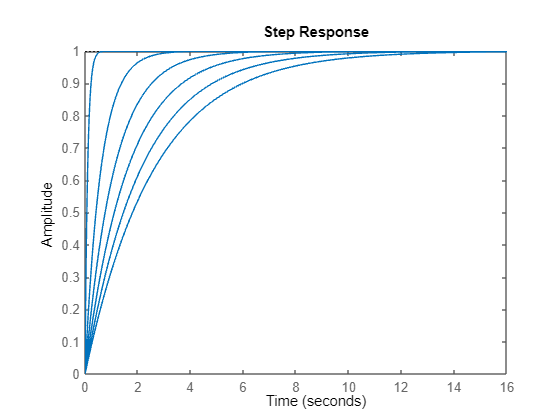

Gs = sampleBlock(G,'tau',0.1:0.5:3);
figure
step(Gs)

برای دسترسی به هر کدام از این توابع میتوانید از اندیس گذاری استفاده کنید

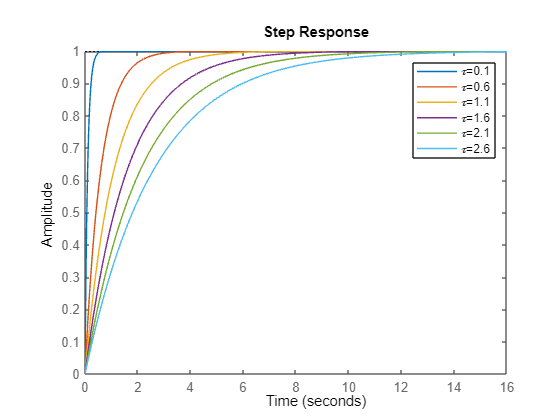

figure; hold on
for i=1:6
    step(Gs(:, :, i, 1))
end
legend('\tau=0.1', '\tau=0.6', '\tau=1.1', '\tau=1.6', '\tau=2.1', '\tau=2.6')

### بررسی تغییرات دو پارامتر

#### مثال

پاسخ پله سیستم زیر را به ازای دو مقدار ثابت میرایی و سه مقدار فرکانس طبیعی  که طبق جایگشت منجر به شش مقدار می شود، را رسم کنید


$$F=\frac{\omega_n^2 }{s^2 +2\zeta \omega_n s+\omega_n^2 }$$


wn = realp('wn',3);
zeta = realp('zeta',0.8);
F = tf(wn^2,[1 2*zeta*wn wn^2])

Generalized continuous-time state-space model with 1 outputs, 1 inputs, 2 states, and the following blocks:
  wn: Scalar parameter, 5 occurrences.
  zeta: Scalar parameter, 1 occurrences.
Model Properties

Type "ss(F)" to see the current value and "F.Blocks" t

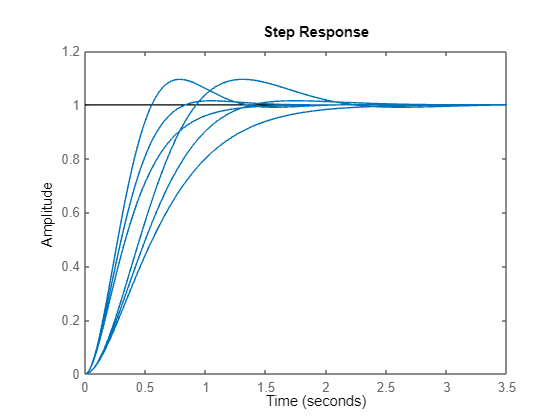

wnvals = [3;5];
zetavals = [0.6 0.8 1.0];
Fsample = sampleBlock(F,'wn',wnvals,'zeta',zetavals);
figure
stepplot(Fsample)

### بررسی تغییرات سه پارامتر

#### مثال

سیستم ساده زیر دارای سه پارامتر قابل تنظیم "ای"، "بی" و "سی" هست. پارامترهای "بی" و "سی" از یکدیگر مستقل نبوده و تغییر یکی به معنای تغییر دیگری است. پارامتر "ای" میتواند مستقل از دو پارامتر دیگر رفتار کند. پاسخ پله سیستم را به ازای تغییرات مختلف این پارامترها رسم کنید


$$G=b\frac{s+c}{s+a}$$


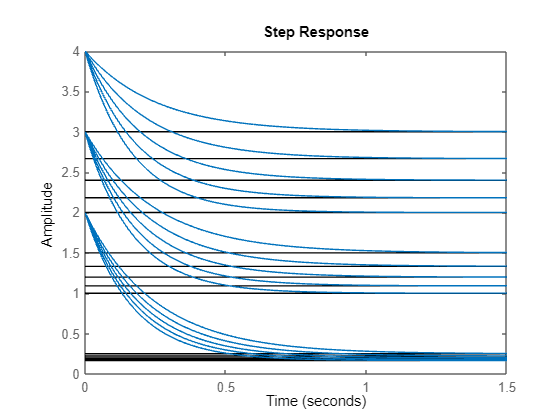

a = realp('a',5);  
b = realp('b',3);  
c = realp('c',2);
G = tf(b*[1 c],[1 a]);
as = 4:0.5:6;
bs = 2:4;
cs = [0.5 2 3];
Gs = sampleBlock(G,'a',as,{'b','c'},{bs,cs});
figure
step(Gs)

## انتخاب نمونه های تصادفی

یک راه مناسب برای استخراج مدل، نمونه برداری تصادفی است. با جایگذاری مقادیر تصادفی به تعداد مناسب در مدل پارامتری، شبیه سازی های مونت کارلو را انجام داده اید. با مراجعه به  سینتکس تابع قبلی و مطالعه آن، این دستورات را بهتر متوجه خواهید شد. سینتکس های زیر به جای جایگذاری بردارهای از پیش تعیین شده، از مقادیر تصادفی تولید شده در آن لحظه استفاده میکند و توابع نمونه برداری شده را استخراج میکند

[`Msamp = rsampleBlock(M,names,N)`](https://127.0.0.1:31515/static/help/control/ref/inputoutputmodel.rsampleblock.html?snc=0EICXH&searchsource=mw%203p&container=jshelpbrowser#d124e140567)

`N: `تعداد نمونه های تصادفی که با جایگذاری مقادیر تصادفی در پارامتر قابل تنظیم مدل بدست می آیند

همانند تابع بخش قبل میتوانید متغیر با هم جفت یا شبکه کنید. سینتکس آن هم مشابه خواهد بود تنها با این تفاوت که بجای بردارها، از اعداد طبیعی که همان تعداد نمونه ها هستند، استفقاده میشود

[`Msamp = rsampleBlock(M,names1,N1,names2,N2,...,namesM,NM)`](https://127.0.0.1:31515/static/help/control/ref/inputoutputmodel.rsampleblock.html?snc=0EICXH&searchsource=mw%203p&container=jshelpbrowser#d124e140599)

این دستور نیز میتواند نقاط تحلیل را برگرداند

[`[Msamp,samples] = rsampleBlock(``___``)`](https://127.0.0.1:31515/static/help/control/ref/inputoutputmodel.rsampleblock.html?snc=0EICXH&searchsource=mw%203p&container=jshelpbrowser#d124e140627)

بدیهی است با هر بار اجرای این دستور، نتایج متفاوتی بدست آید

### بررسی تغییرات یک پارامتر

#### مثال

پاسخ پله سیستم زیر را به ازای شش مقدار مختلف ثابت زمانی از 0.1 تا 3 ثانیه بررسی کنید


$$G=\frac{1}{\tau s+1}$$


tau = realp('tau',5);
tau.Maximum = 3; tau.Minimum = 0.1;
G = tf(1,[tau 1])

Generalized continuous-time state-space model with 1 outputs, 1 inputs, 1 states, and the following blocks:
  tau: Scalar parameter, 1 occurrences.
Model Properties

Type "ss(G)" to see the current value and "G.Blocks" to interact with the blocks.


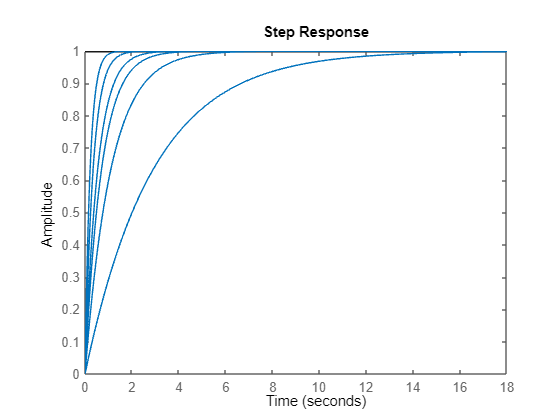

Gs = rsampleBlock(G,'tau',6);
figure
step(Gs)

### بررسی تغییرات دو پارامتر

#### مثال

پاسخ پله سیستم زیر را به ازای دو مقدار ثابت میرایی و سه مقدار فرکانس طبیعی  که طبق جایگشت منجر به شش مقدار می شود، را رسم کنید


$$F=\frac{\omega_n^2 }{s^2 +2\zeta \omega_n s+\omega_n^2 }$$


wn = realp('wn',3);
wn.Maximum = 5; wn.Minimum = 3;
zeta = realp('zeta',0.8);
zeta.Maximum = 1; zeta.Minimum = 0.6;
F = tf(wn^2,[1 2*zeta*wn wn^2])

Generalized continuous-time state-space model with 1 outputs, 1 inputs, 2 states, and the following blocks:
  wn: Scalar parameter, 5 occurrences.
  zeta: Scalar parameter, 1 occurrences.
Model Properties

Type "ss(F)" to see the current value and "F.Blocks" t

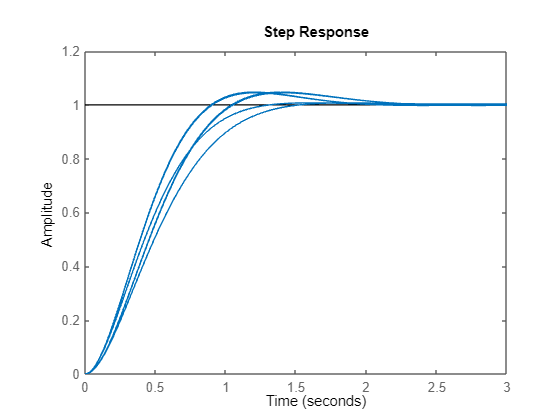

Fsample = rsampleBlock(F,'wn',2,'zeta',3);
figure
stepplot(Fsample)

### بررسی تغییرات سه پارامتر

#### مثال

سیستم ساده زیر دارای سه پارامتر قابل تنظیم "ای"، "بی" و "سی" هست. پارامترهای "بی" و "سی" از یکدیگر مستقل نبوده و تغییر یکی به معنای تغییر دیگری است. پارامتر "ای" میتواند مستقل از دو پارامتر دیگر رفتار کند. پاسخ پله سیستم را به ازای تغییرات مختلف این پارامترها رسم کنید


$$G=b\frac{s+c}{s+a}$$


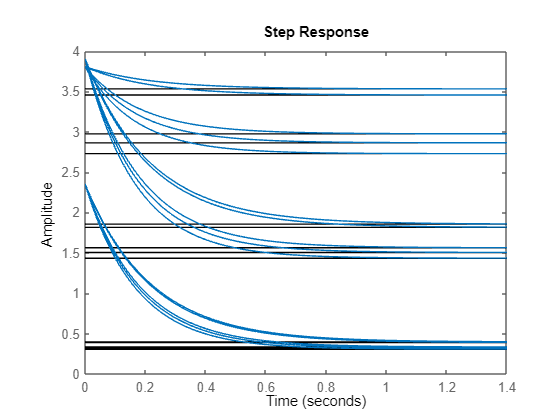

a = realp('a',5);
a.Maximum = 6; a.Minimum = 4;
b = realp('b',3);
b.Maximum = 4; b.Minimum = 2;
c = realp('c',2);
c.Maximum = 6; c.Minimum = 0.5;
G = tf(b*[1 c],[1 a]);
Gs = rsampleBlock(G,'a',5,{'b','c'},3);
figure
step(Gs)